# **Ciclo For (Ejemplos)**

**Una pequeña introduccion con ciclo for & if**

clc; clear;
m=randi([-5,5],1,9);
x=1:length(m);
plot(x,m,'w.-',"LineWidth",2);grid;
hold on
%text(2,0,'Gráfica',"FontSize",16);
%legend('Gráfica Random');
%El texto es fijo respecto a la grafica, no maximiza ni minimiza.
[max_m i_m]=max(m);
[min_m i_n]=min(m);
%para encontarar cada uno de los maximos usamos
%find(m==max(m))
for i=1:length(m)
    texto=['(' num2str(i) ',' num2str(m(i)) ')' ]
    if max_m==m(i) %i == i_m
        texto=['Max(' num2str(i) ',' num2str(m(i)) ')' ]
        text(i+0.5,m(i)-0.5,texto,"FontSize",16,'Color',[0 0 1])
    else
        if min_m==m(i) %i == i_m
        texto=['Min(' num2str(i) ',' num2str(m(i)) ')' ]
        text(i+0.5,m(i)+0.5,texto,"FontSize",16,'Color',[1 0 0])
        plot(i,m(i),'ks','MarkerSize',15);
        else
        text(i,m(i),texto,"FontSize",16)
        end
        
    end
    
end

texto = '(1,-4)'

texto = '(2,1)'

texto = '(3,-3)'

texto = '(4,2)'

texto = '(5,2)'

texto = '(6,3)'

texto = 'Max(6,3)'

texto = '(7,-1)'

texto = '(8,-5)'

texto = 'Min(8,-5)'

texto = '(9,-3)'

for i=1:length(m)-1
    d = m(i+1)-m(i)%/x(i+1)-x(i)
    if d<0
        plot([x(i) x(i+1)],[m(i) m(i+1)],'b-')
        px=mean([x(i) x(i+1)])
        py=mean([m(i) m(i+1)])
        text(px,py,'neg', "FontSize",16, 'Color',[0 0 1]);
    
    elseif d>0
        plot([x(i) x(i+1)],[m(i) m(i+1)],'r-')
        px=mean([x(i) x(i+1)])
        py=mean([m(i) m(i+1)])
        text(px,py,'pos', "FontSize",16,"Color",[1 0 0]);
    else
        plot([x(i) x(i+1)],[m(i) m(i+1)],'g-')
        px=mean([x(i) x(i+1)])
        py=mean([m(i) m(i+1)])
        text(px,py+0.5,'const', "FontSize",16,"Color",[0 1 0]);
    end
    
end

d = 5

px = 1.5000

py = -1.5000

d = -4

px = 2.5000

py = -1

d = 5

px = 3.5000

py = -0.5000

d = 0

px = 4.5000

py = 2

d = 1

px = 5.5000

py = 2.5000

d = -4

px = 6.5000

py = 1

d = -4

px = 7.5000

py = -3

d = 2

px = 8.5000

py = -4

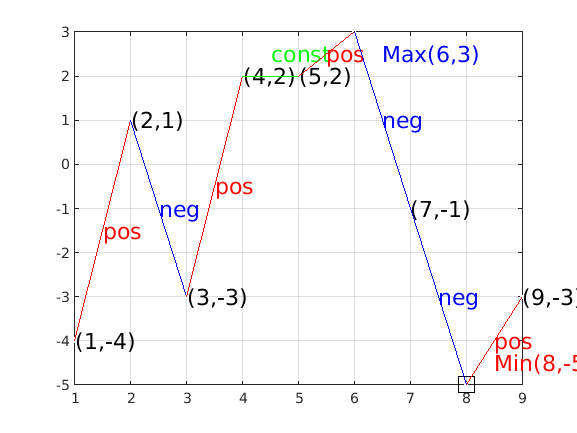

%La funcion mean saca el promedio de los puntos del arreglo.
hold off